tic
% Bifurification parameter
Gin = 0:5:300;
nValues = length(Gin);

%Constants for all trials
const = models.constants;
const.tau1 = 7;
const.tau2 = 36;
const.td = 36;

constArray(1:nValues) = const;

% Initial conditions
% Li et al
liState = [13000; % Glucose
         30]; % Insulin
% Sturis et al. and Tolic et al conditions
sturisState = [30; % Ip
               0; % Ii
               14000; % G
               0; % x1
               0; % x2
               0]; % x3

% Simulation time               
time = [0, 10000];
tmin = 0.9*time(2);

% Vectors for results
% Form: min G, max G, min I, max I
LiResults = zeros(nValues, 4);
SturisResults = zeros(nValues, 4);
tolicResults = zeros(nValues, 4);

% Store Values for each parameter
parfor i=1:nValues
    % Update Gin value
    constArray(i).Gin = Gin(i);
    
    % Solve Equations
    sol = liSolver(liState, constArray(i), time);
    [t, y] = sturisSolver(sturisState, constArray(i), time);
    [tT, yT] = tolicSolver(sturisState, const, time);
    
    % Store Results
    LiResults(i,:) = [min(sol.y(1,sol.x>tmin)), max(sol.y(1,sol.x>tmin))...
                      min(sol.y(2,sol.x>tmin)), max(sol.y(2,sol.x>tmin))];
    SturisResults(i,:) = [min(y(t>tmin,3)), max(y(t>tmin,3))...
                      min(y(t>tmin,1)), max(y(t>tmin,1))];
    TolicResults(i,:) = [min(yT(tT>tmin,3)), max(yT(tT>tmin,3))...
                         min(yT(tT>tmin,1)), max(yT(tT>tmin,1))];
end


toc

Elapsed time is 71.774405 seconds.


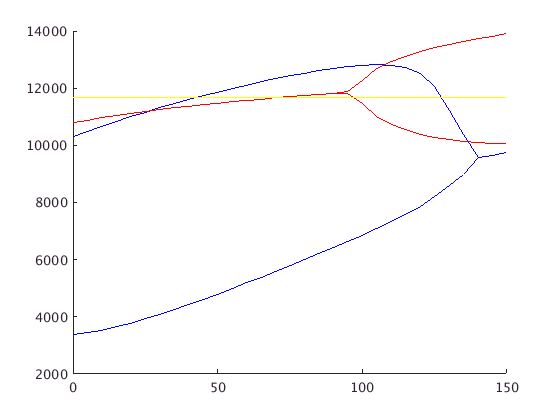

%%
hold on
plot(Gin, LiResults(:,1), 'b')
plot(Gin, LiResults(:,2), 'b')
plot(Gin, SturisResults(:,1), 'r')
plot(Gin, SturisResults(:,2), 'r')
plot(Gin, TolicResults(:,1), 'y')
plot(Gin, TolicResults(:,2), 'y')
hold off